## TCLab Step Test Simulation

Goal: Compare Step response data to simulated data from TCLab

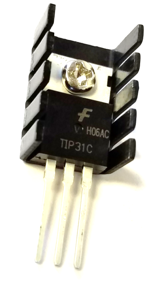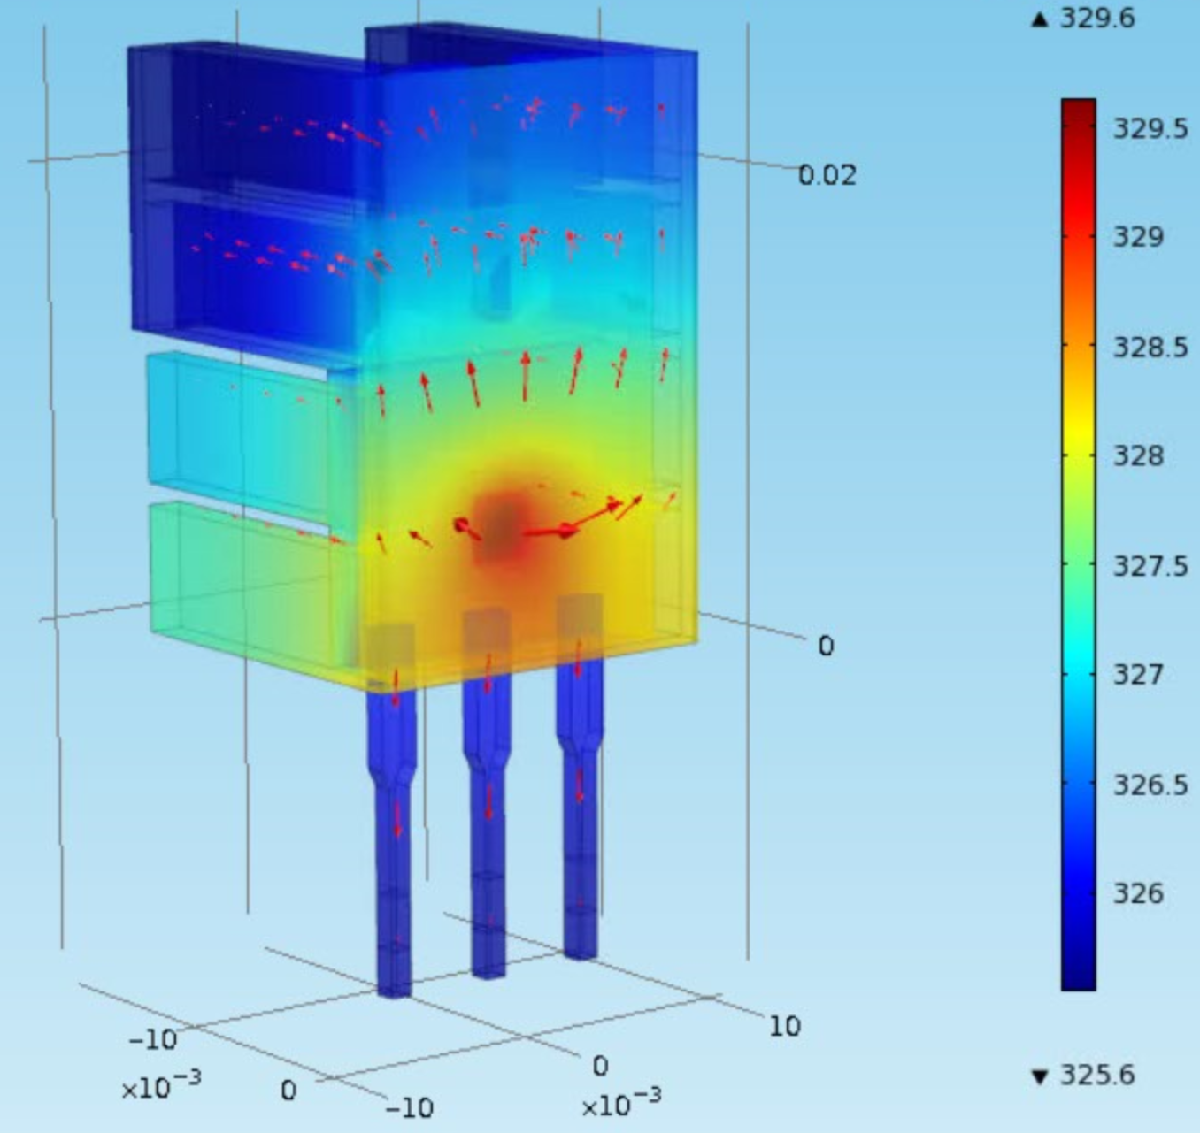

Simplified dymanic model of TCLab:


$$\tau_p\frac{dT}{dt}=(T_a-T) +K_pQ$$


With the temperature initially at ambient temperature ($Ta$), simulate the change in temperature over the 5 minutes when heater $Q$ is adjusted to $50\%$. Use a values of $\tau = 120$ sec, $K_p = 0.8 \frac{^\circ C}{\%}$, and $T_a =23^\circ C$. Compare the simulated temperature response to data from the TCLab. Add a simulation prediction to the script below to compare with the TCLab data.

### TCLab Step Response

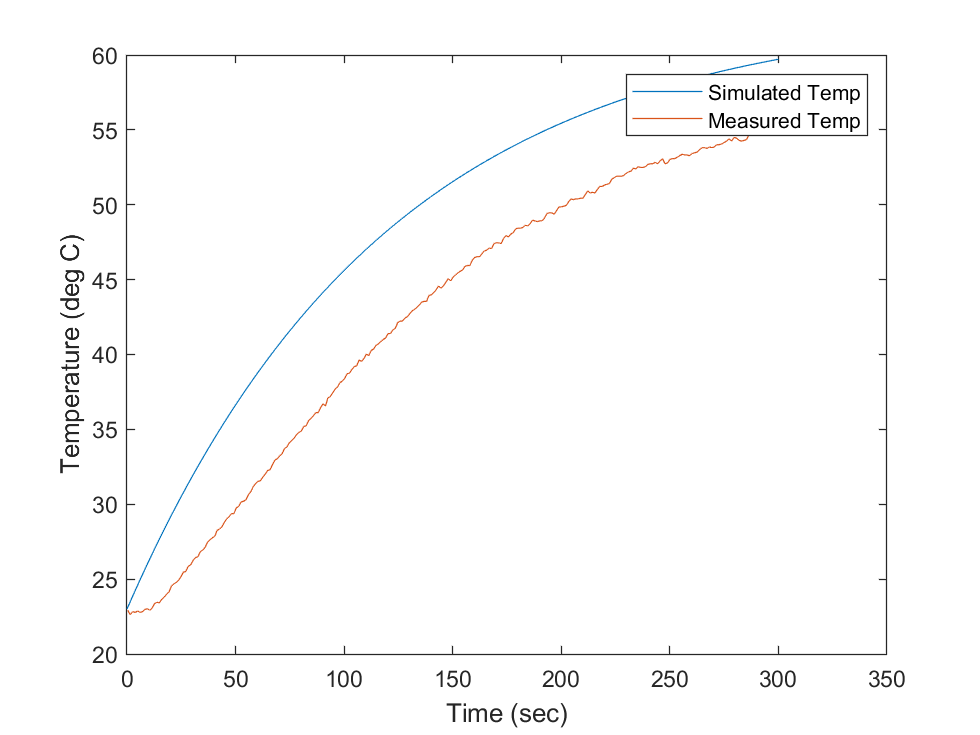

% clear code
clc;clear all;close all;
try
    % initialize storage array
    T1 = zeros(301, 1);
    tm = zeros(301, 1);
    
    % connect to TCLab

    lab = tclab;
    lab.Q1(50);
    tic;
    for i=1:length(times)
        T1(i) = lab.T1;
        tm(i) = toc;
        pause(1);
        
    end
    lab.off;
    clear lab;

catch
    lab.off;
    clear lab;
end    

### Simulation

Simulate the change in temperature as the heater is set to 50% for 5 minutes

% ADD SIMULATION DATA BELOW
%%%%%%%%%%%%%%%%%%%%


% ADD PLOT OF SIMULATION AND STEP_TEST BELOW
%%%%%%%%%%%%%%%%%%%%%


% ADD FUNCTION TO INTEGRATE BELOW
%%%%%%%%%%%%%%%%%%%%%

### Solution

[insert solution video here]